# Laboratory 6


$$\begin{array}{l}
y\left(t\right)=L^{-1} \left\lbrace Y\left(s\right)\right\rbrace =L^{-1} \left\lbrace H\left(s\right)U\left(s\right)\right\rbrace |_{U\left(s\right)=\frac{1}{s}} =L^{-1} \left\lbrace \frac{H\left(s\right)}{s}\right\rbrace \\
y\left(t\right)=\sum_{i=0}^r \frac{R_i }{S-S_i }+\sum_{j=0}^{\frac{C}{2}} \frac{b_{1j} s+b_{0j} }{s^2 +a_{1j} s+a_{0j} }+R_{\infty } 
\end{array}$$


### Solved example

Declare the next transfer function in Matlab; use also the conv function to introduce the denominator of the transfer function.


$$H\left(s\right)=\frac{2s+5}{s^4 +7s^3 +21s^2 +37s+30}=\frac{2s+5}{\left(s^2 +5s+6\right)\left(s^2 +2s+5\right)}$$


clear variables;

num = [2 5]

num =      2     5


den = conv([1 5 6],[1 2 5])

den =      1     7    21    37    30


H = tf(num, den)

H =
 
              2 s + 5
  --------------------------------
  s^4 + 7 s^3 + 21 s^2 + 37 s + 30
 
Continuous-time transfer function.



zpk(H)

ans =
 
          2 (s+2.5)
  --------------------------
  (s+2) (s+3) (s^2 + 2s + 5)
 
Continuous-time zero/pole/gain model.



Call the residue function in order to store the residues of the terms in R,

the poles in P and the residue at infinity in R_inf:

[R,P,R_inf]=residue(num, [den 0])

R =   -0.0417 + 0.0000i
  -0.0125 + 0.0875i
  -0.0125 - 0.0875i
  -0.1000 + 0.0000i
   0.1667 + 0.0000i


P =   -3.0000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i
  -2.0000 + 0.0000i
   0.0000 + 0.0000i



R_inf =

     []




syms s

t1 = ilaplace(R(1) ./ (s - P(1)))

$$t1 = -\frac{{\mathrm{e}}^{-3\,t}}{24}$$

t2 = ilaplace(R(2) ./ (s - P(2)) + R(3) ./ (s - P(3)))

$$t2 = {\mathrm{e}}^{t\,\left(-1-2\,\mathrm{i}\right)}\,\left(-\frac{1}{80}-\frac{7}{80}\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(-1+2\,\mathrm{i}\right)}\,\left(-\frac{1}{80}+\frac{7}{80}\,\mathrm{i}\right)$$

t3 = ilaplace(R(4) ./ (s - P(4)))

$$t3 = -\frac{{\mathrm{e}}^{-2\,t}}{10}$$

t4 = ilaplace(R(5) ./ (s - P(5)))

$$t4 = \frac{1}{6}$$

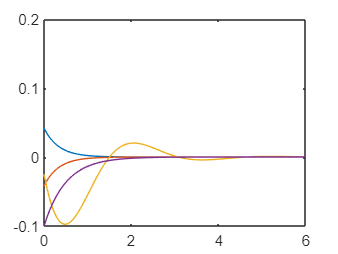


tf0 = 6;
t = linspace(0,tf0,100);

plot(t,exp(-3*t)/24);
hold on;
plot(t, -1 * exp(-3*t)/24);
plot(t, -1 /40 * exp(-1 .* t) .* (cos(2 .* t) + 7 .* sin(2 * t)));
plot(t, -1/10 * exp(-2 * t));
plot(t, 1/6);
hold off;

### Problems

Follow the same requests as in the solved example for the next transfer functions:

1) $H\left(s\right)=\frac{1}{1000s}\;!\mathrm{the}\;\mathrm{integrator}\;H\left(s\right)=\frac{1}{\mathrm{RCs}},R=1k\Omega ,C=1\mu F$

clear variables;

num = [0 1]

num =      0     1


den = [1000 0]

den =         1000           0



H = tf(num, den)

H =
 
    1
  ------
  1000 s
 
Continuous-time transfer function.



zpk(H)

ans =
 
  0.001
  -----
    s
 
Continuous-time zero/pole/gain model.




[R,P,R_inf]=residue(num, [den 0])

R = 	1.0e+-3 *

         0
    1.0000


P =      0
     0



R_inf =

     []




syms s

t1 = ilaplace(R(1) / (s - P(1)))

$$t1 = 0$$

t2 = ilaplace(R(2) / (s - P(2)))

$$t2 = \frac{1}{1000}$$

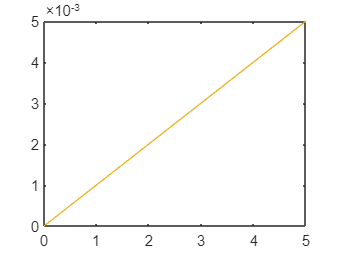


tf0 = 5;
t = linspace(0,tf0,100);

figure,
plot(t,0);
hold on;
plot(t, 1/1000 * t);

2) $H\left(s\right)=\frac{1}{1000s+1}$

clear variables;

num = [0 1]

num =      0     1


den = [1000 1]

den =         1000           1



H = tf(num, den)

H =
 
      1
  ----------
  1000 s + 1
 
Continuous-time transfer function.



zpk(H)

ans =
 
    0.001
  ---------
  (s+0.001)
 
Continuous-time zero/pole/gain model.




[R,P,R_inf]=residue(num, [den 0])

R = 	1.0e+-3 *

         0
    1.0000


P = 	1.0e+-3 *

   -0.5000
   -0.5000



R_inf =

     []




syms s

t1 = ilaplace(R(1) / (s - P(1)))

$$t1 = 0$$

t2 = ilaplace(R(2) / (s - P(2)))

$$t2 = \frac{{\mathrm{e}}^{-\frac{t}{2000}}}{1000}$$

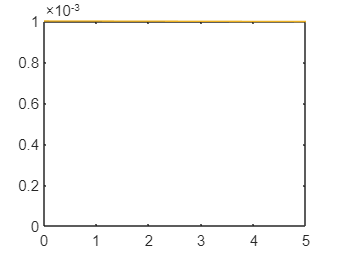


tf0 = 5;
t = linspace(0,tf0,100);

figure,
plot(t,0);
hold on;
plot(t, exp(-t/2000)/1000);
hold off;

3) $H\left(s\right)=\frac{3s+1}{s+0\ldotp 5}$

clear variables;

num = [3 1]

num =      3     1


den = [1 1/2]

den =     1.0000    0.5000



H = tf(num, den)

H =
 
  3 s + 1
  -------
  s + 0.5
 
Continuous-time transfer function.



zpk(H)

ans =
 
  3 (s+0.3333)
  ------------
    (s+0.5)
 
Continuous-time zero/pole/gain model.




[R,P,R_inf]=residue(num, [den 0])

R =      1
     2


P =    -0.5000
         0



R_inf =

     []




syms s

t1 = ilaplace(R(1) / (s - P(1)))

$$t1 = {\mathrm{e}}^{-\frac{t}{2}}$$

t2 = ilaplace(R(2) / (s - P(2)))

$$t2 = 2$$

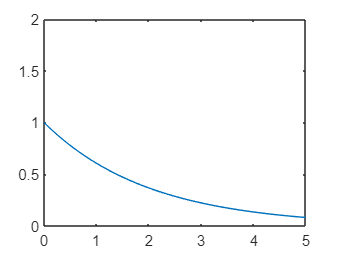


tf0 = 5;
t = linspace(0,tf0,100);

figure,
plot(t,exp(-t/2));
hold on;
plot(t, 2);
hold off;

4) $H\left(s\right)=\frac{20}{\left(s+5\right)\left(s+3\right)}$

clear variables;

%syms s
%expand((s+5)*(s+3))

num = [0 0 20]

num =      0     0    20


den = conv([0 1 5], [0 1 3])

den =      0     0     1     8    15



H = tf(num, den)

H =
 
        20
  --------------
  s^2 + 8 s + 15
 
Continuous-time transfer function.



zpk(H)

ans =
 
      20
  -----------
  (s+5) (s+3)
 
Continuous-time zero/pole/gain model.




[R,P,R_inf]=residue(num, [den 0])

R =     2.0000
   -3.3333
    1.3333


P =     -5
    -3
     0



R_inf =

     []




syms s

t1 = ilaplace(R(1) / (s - P(1)))

$$t1 = 2\,{\mathrm{e}}^{-5\,t}$$

t2 = ilaplace(R(2) / (s - P(2)))

$$t2 = -\frac{10\,{\mathrm{e}}^{-3\,t}}{3}$$

t3 = ilaplace(R(3) / (s - P(3)))

$$t3 = \frac{4}{3}$$

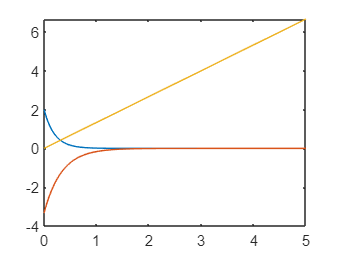


tf0 = 5;
t = linspace(0,tf0,100);

figure,
plot(t,2*exp(-5*t));
hold on;
plot(t, -10*exp(-3*t)/3);
plot(t, 4/3*t);
hold off;

5) $H\left(s\right)=\frac{3s}{s+2}$

clear variables;

num = [0 3 0]

num =      0     3     0


den = [1 2]

den =      1     2



H = tf(num, den)

H =
 
   3 s
  -----
  s + 2
 
Continuous-time transfer function.



zpk(H)

ans =
 
   3 s
  -----
  (s+2)
 
Continuous-time zero/pole/gain model.




[R,P,R_inf]=residue(num, [den 0])

R =      3
     0


P =     -2
     0



R_inf =

     []




syms s

t1 = ilaplace(R(1) / (s - P(1)))

$$t1 = 3\,{\mathrm{e}}^{-2\,t}$$

t2 = ilaplace(R(2) / (s - P(2)))

$$t2 = 0$$

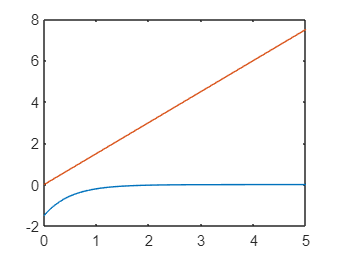


tf0 = 5;
t = linspace(0,tf0,100);

figure,
plot(t,-3*exp(-2*t)/2);
hold on;
plot(t, 3/2*t);
hold off;

6) $H\left(s\right)=\frac{21}{s\left(s+7\right)}$

clear variables;

num = [0 0 21]

num =      0     0    21


den = conv([0 1 0], [0 1 7])

den =      0     0     1     7     0



H = tf(num, den)

H =
 
     21
  ---------
  s^2 + 7 s
 
Continuous-time transfer function.



zpk(H)

ans =
 
    21
  -------
  s (s+7)
 
Continuous-time zero/pole/gain model.




[R,P,R_inf]=residue(num, [den 0])

R =     0.4286
   -0.4286
    3.0000


P =     -7
     0
     0



R_inf =

     []




syms s

t1 = ilaplace(R(1) / (s - P(1)))

$$t1 = \frac{3\,{\mathrm{e}}^{-7\,t}}{7}$$

t2 = ilaplace(R(2) / (s - P(2)))

$$t2 = -\frac{3}{7}$$

t3 = ilaplace(R(3) / (s - P(3)))

$$t3 = 3$$

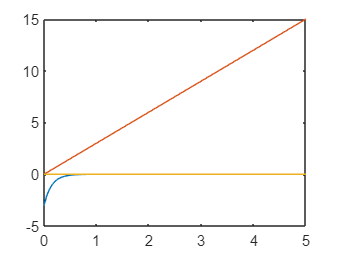


tf0 = 5;
t = linspace(0,tf0,100);

figure,
plot(t,-3*exp(-7*t));
hold on;
plot(t, 3*t);
plot(t, 0*t);
hold off;

7) $H\left(s\right)=\frac{16}{s^2 +2s+16}$

clear variables;

num = [0 0 16]

num =      0     0    16


den = [1 2 16]

den =      1     2    16



H = tf(num, den)

H =
 
        16
  --------------
  s^2 + 2 s + 16
 
Continuous-time transfer function.



zpk(H)

ans =
 
        16
  ---------------
  (s^2 + 2s + 16)
 
Continuous-time zero/pole/gain model.




[R,P,R_inf]=residue(num, [den 0])

R =   -0.5000 + 0.1291i
  -0.5000 - 0.1291i
   1.0000 + 0.0000i


P =   -1.0000 + 3.8730i
  -1.0000 - 3.8730i
   0.0000 + 0.0000i



R_inf =

     []




syms s

t1 = ilaplace(R(1) / (s - P(1)) + (R(2) / (s - P(2))))

$$t1 = {\mathrm{e}}^{t\,\left(-1+\sqrt{15}\,\mathrm{i}\right)}\,\left(-\frac{1}{2}+\frac{\sqrt{15}\,\mathrm{i}}{30}\right)-{\mathrm{e}}^{-t\,\left(1+\sqrt{15}\,\mathrm{i}\right)}\,\left(\frac{1}{2}+\frac{\sqrt{15}\,\mathrm{i}}{30}\right)$$

t2 = ilaplace(R(3) / (s - P(3)))

$$t2 = 1$$

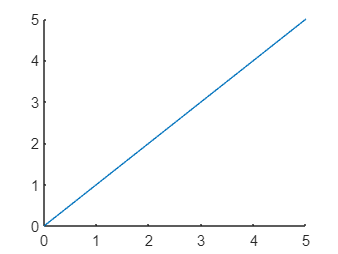


tf0 = 5;
t = linspace(0,tf0,100);

figure,
%plot(t,exp(t * (-1+sqrt(15)i))*(-1/2+sqrt(15)i/30) - exp(-t*(1+sqrt(15)i))*(1/2+sqrt(15)i/30));
hold on;
plot(t, 1*t);
hold off;

8) $H\left(s\right)=\frac{9}{s^2 +9}$

clear variables;

num = [0 0 9]

num =      0     0     9


den = [1 0 9]

den =      1     0     9



H = tf(num, den)

H =
 
     9
  -------
  s^2 + 9
 
Continuous-time transfer function.



zpk(H)

ans =
 
      9
  ---------
  (s^2 + 9)
 
Continuous-time zero/pole/gain model.




[R,P,R_inf]=residue(num, [den 0])

R =    -0.5000
   -0.5000
    1.0000


P =    0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 0.0000i



R_inf =

     []




syms s

t1 = ilaplace(R(1) / (s - P(1)) + (R(2) / (s - P(2))))

$$t1 = -\frac{{\mathrm{e}}^{-3\,t\,\mathrm{i}}}{2}-\frac{{\mathrm{e}}^{3\,t\,\mathrm{i}}}{2}$$

t2 = ilaplace(R(3) / (s - P(3)))

$$t2 = 1$$

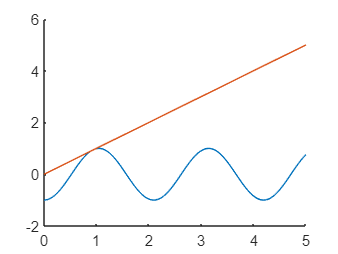


tf0 = 5;
t = linspace(0,tf0,100);

figure,
hold on;
plot(t,-exp(-3*t*1i)/2-exp(3*t*1i)/2)
plot(t, 1*t);
hold off;

9) $H\left(s\right)=\frac{12}{\left(s-4\right)\left(s+2\right)}$

clear variables;

num = [0 0 16]

num =      0     0    16


den = conv([0 1 -4], [0 1 2])

den =      0     0     1    -2    -8



H = tf(num, den)

H =
 
       16
  -------------
  s^2 - 2 s - 8
 
Continuous-time transfer function.



zpk(H)

ans =
 
      16
  -----------
  (s-4) (s+2)
 
Continuous-time zero/pole/gain model.




[R,P,R_inf]=residue(num, [den 0])

R =     0.6667
    1.3333
   -2.0000


P =      4
    -2
     0



R_inf =

     []




syms s

t1 = ilaplace(R(1) / (s - P(1)) + (R(2) / (s - P(2))))

$$t1 = \frac{4\,{\mathrm{e}}^{-2\,t}}{3}+\frac{2\,{\mathrm{e}}^{4\,t}}{3}$$

t2 = ilaplace(R(3) / (s - P(3)))

$$t2 = -2$$

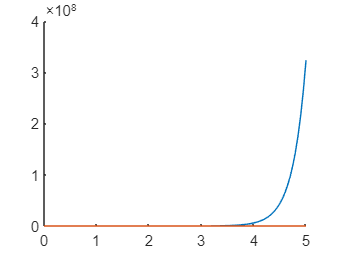


tf0 = 5;
t = linspace(0,tf0,100);

figure,

hold on;
plot(t,4*exp(-2*t)/3+2*exp(4*t)/3)
plot(t, -2*t);
hold off;

10) $H\left(s\right)=\frac{12}{s^2 -4}$

clear variables;

num = [0 0 12]

num =      0     0    12


den = [1 0 -4]

den =      1     0    -4



H = tf(num, den)

H =
 
    12
  -------
  s^2 - 4
 
Continuous-time transfer function.



zpk(H)

ans =
 
      12
  -----------
  (s-2) (s+2)
 
Continuous-time zero/pole/gain model.




[R,P,R_inf]=residue(num, [den 0])

R =     1.5000
    1.5000
   -3.0000


P =     2.0000
   -2.0000
         0



R_inf =

     []




syms s

t1 = ilaplace(R(1) / (s - P(1)) + (R(2) / (s - P(2))))

$$t1 = \frac{3\,{\mathrm{e}}^{-2\,t}}{2}+\frac{3\,{\mathrm{e}}^{2\,t}}{2}$$

t2 = ilaplace(R(3) / (s - P(3)))

$$t2 = -3$$

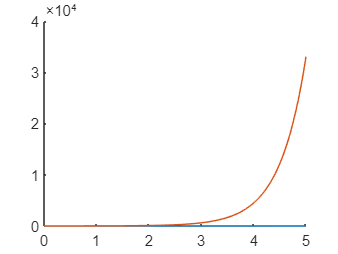


tf0 = 5;
t = linspace(0,tf0,100);

figure,

hold on;
plot(t, -3.*t);
plot(t,3*exp(-2*t)/2+3*exp(2*t)/2)
hold off;